clear

path = 'C:\Users\franc\Desktop\BIOMECCANICA';

pop = dir(path); pop = {pop(3:end).name};

[indx,~] = listdlg('ListString',pop);
pop_true = pop(indx);


file_to_load = {'ROOT' 'INDIP' 'LWRIST' 'RWRIST' 'LFOOT' 'RFOOT' 'LBACK' 'STERN' 'FHEAD'};
[indx,~] = listdlg('ListString',file_to_load);
file_true = file_to_load(indx);
TAB = table;
TAB1 = table;

%Carico tutta la tabella TAB
for po = 1:length(pop_true)

    files = dir([path '\' char(pop_true(po))]); files = {files(3:end).name};
    files_true = files(contains(files,file_true));

    for fi = 1:length(files_true)

        temp = load([path '\' char(pop_true(po)) '\' char(files_true(fi))]);
        fld = char(fieldnames(temp)); ind = strfind(fld,'_');
        if contains(fld,'INDIP') == 1 || contains(fld,'ROOT') == 1
            temp = temp.(fld);
        else
            temp = table(temp.(fld));
            temp.Properties.VariableNames = {fld(ind+1:end)};
        end
        TAB1 = [TAB1 temp];

    end

    TAB = [TAB; TAB1];

    TAB1 = table;
end

TAB = removevars(TAB,'b2');
varnames = TAB.Properties.VariableNames;
varnames(contains(varnames,'b1')) = {'INDIP'};

TAB.Properties.VariableNames = varnames;

TAB =  movevars(TAB,'GROUP','Before',1); TAB = movevars(TAB,{'SUBJECT' 'TASK' 'TRIAL' 'ORIGINAL PATH' 'AGE' 'MASS' 'HEIGHT' 'INDIP'},'After','GROUP');

for ii = 1:size(TAB,1)
    TAB.HEIGHT{ii} = cell2mat(TAB.HEIGHT(ii))*0.53;
end


c = contains(TAB.("ORIGINAL PATH"),'FAST');
TAB = TAB(c,:);

timing = repmat({'T0'},size(TAB,1),1);

TAB.TIMING = timing;
TAB = movevars(TAB,'TIMING','Before','TASK');

%% CLEANING
for ii = 1:size(TAB,1)

    mwb = TAB.INDIP(ii).MicroWB;

    ind(ii) =   isempty(mwb);
end

ind = logical(ind);
TAB(ind,:) = [];
ind = [];

for ii = 1:size(TAB,1)

    mwb = TAB.FHEAD(ii).acc;

    ind(ii) =   isempty(mwb);
end

ind = logical(ind);
TAB(ind,:) = [];
ind = [];


for ii = 1:size(TAB,1)

    mwb = TAB.LBACK(ii).acc;
    ind(ii) =   isempty(mwb);
end

ind = logical(ind);
TAB(ind,:) = [];
ind = [];


for ii = 1:size(TAB,1)

    mwb = TAB.STERN(ii).acc;

    ind(ii) =   isempty(mwb);
end

ind = logical(ind);
TAB(ind,:) = [];
ind = [];


% %% GET SPATIOTEMPORAL
for ii = 1:size(TAB,1)

    mwb = TAB.INDIP(ii).MicroWB;

    TAB.STRIDE_FQ(ii) = {nanmean(cell2mat({mwb.StrideFrequency}))};


    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stride_Length;
        spa = [spa temp];
    end

    TAB.STRIDE_LENGTH(ii) = {(spa)};


    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stride_Speed;
        spa = [spa temp];
    end


    TAB.STRIDE_SPEED(ii) = {(spa)};


    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stride_Duration;
        spa = [spa temp];
    end

    TAB.STRIDE_DURATION(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stride_Length;
        spa = [spa temp];
    end

    TAB.STRIDE_LENGTH(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stance_Duration;
        spa = [spa temp];
    end

    TAB.STANCE_DURATION(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stance_Length;
        spa = [spa temp];
    end

    TAB.STANCE_LENGTH(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stance_Speed;
        spa = [spa temp];
    end

    TAB.STANCE_SPEED(ii) = {(spa)};


    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Swing_Duration;
        spa = [spa temp];
    end

    TAB.SWING_DURATION(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Swing_Length;
        spa = [spa temp];
    end

    TAB.SWING_LENGTH(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Swing_Speed;
        spa = [spa temp];
    end

    TAB.SWING_SPEED(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).SingleSupport_Duration;
        spa = [spa temp];
    end

    TAB.SS_DURATION(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).DoubleSupport_Duration;
        spa = [spa temp];
    end

    TAB.DS_DURATION(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).Stride_InitialContacts;
        spa = [spa; temp];
    end

        [r,c] = find(isnan(spa)); r = unique(r); spa(r,:) = [];
    TAB.CONTANCTS(ii) = {(spa)};

    spa = [];

    for jj = 1:size(mwb,2)
        temp = mwb(jj).FinalContact_LeftRight;
        spa = [spa temp];
    end

    %     spa(:,r) = [];
    TAB.SIDE(ii) = {(spa)};


end

Dividiamo in TAB10 e TAB8

% Selezioniamo le righe in cui TASK è '10MWT' (cammino rettilineo)
TAB10 = TAB(strcmp(TAB.TASK, '10MWT'), :)

TAB10 = 680×27 table
           GROUP           SUBJECT    TIMING      TASK                         TRIAL                                                                                                                   ORIGINAL PATH                                                                                                 AGE       MASS       HEIGHT        INDIP         FHEAD         LBACK         STERN        STRIDE_FQ                                                                      STRIDE_LENGTH                                                                                                                                      STRIDE_SPEED                                                                      


% Selezioniamo le righe in cui TASK è '8MWT' (cammino a 8)
TAB8 = TAB(strcmp(TAB.TASK, 'Fo8WT'), :)

TAB8 = 829×27 table
           GROUP           SUBJECT    TIMING      TASK                         TRIAL                                                                                                                   ORIGINAL PATH                                                                                                 AGE       MASS       HEIGHT        INDIP         FHEAD         LBACK         STERN        STRIDE_FQ                                                           STRIDE_LENGTH                                                                                                                  STRIDE_SPEED                                                                                                      

Creo una tabella ridotta (TABreduced), rispetto al task '10MTW' (TAB10), contenente le prime 15 righe per ogni malattia

TABreduced = table; % Inizializzo una tabella vuota per il risultato

% Filtro i gruppi per ciascun tipo di malattia solo per TASK = '10MWT'+
groups = {'Healthy_Control', 'PD', 'STROKE', 'TBI'};
start_rows = [1, 254, 413, 602]; % Indici di inizio per ogni gruppo
end_rows = [253, 412, 601, 680]; % Indici di fine per ogni gruppo

for i = 1:length(groups)
    % Seleziono le righe per il gruppo corrente da TAB10
    group_data = TAB10(strcmp(TAB10.GROUP, groups{i}), :);

    % Prendo solo le prime 15 righe 
    num_rows = min(15, size(group_data, 1));   %prendo al massimo 15 righe del gruppo, ma se il gruppo ha meno di 15 righe, allora prenderai tutte le righe disponibili. Quindi, se il gruppo ha meno di 15 righe, il codice prende tutte le righe, altrimenti prende solo le prime 15 righe.
    group_data_reduced = group_data(1:num_rows, :);    %Seleziona le righe dalla 1 alla num_rows (ad esempio, se ci sono 10 righe, prende le righe da 1 a 10).

    % Aggiungo i dati ridotti a TABreduced
    TABreduced = [TABreduced; group_data_reduced];

    end


**Calcolo, per tutte le malattie, il CV.**

**CV = 100SD∕mean where mean is the mean step length and SD is the standard deviation over the entire step length for each subject. The higher the CV, the higher is the variability of the step length. **Un valore **basso** del CV indica una maggiore **regolarità** (i passi sono più simili tra loro), mentre un valore **alto** indica una maggiore **variabilità** tra gli stride.


CV_individuale = zeros(height(TABreduced),1); 

for ii = 1:height(TABreduced)
    stride = TABreduced.STRIDE_LENGTH{ii}; 
    CV_ind = 100 * std(stride,'omitmissing') / mean(stride,'omitmissing');
    CV_individuale(ii) = CV_ind;
end

% Aggiungo la colonna alla tabella
TABreduced.CV_individuale = CV_individuale;

**CV della stride_length medio per gruppo**

CV_Healthy = mean(TABreduced.CV_individuale(1:15))

CV_Healthy = 3.8361

CV_PD = mean(TABreduced.CV_individuale(16:30))

CV_PD = 9.7193

CV_ST = mean(TABreduced.CV_individuale(31:45))

CV_ST = 5.1008

CV_TBI= mean(TABreduced.CV_individuale(46:60))

CV_TBI = 5.7056

**PCI individuale per tutti i pazienti**


PCI_individuale = zeros(height(TABreduced),1); %creo nuova colonna

for ii = 1:height(TABreduced)


ic_times = TABreduced.INDIP(ii).ContinuousWalkingPeriod.InitialContact_Event;
ic_side  = TABreduced.INDIP(ii).ContinuousWalkingPeriod.InitialContact_LeftRight;

% Assicurati siano colonne
ic_times = ic_times(:);
ic_side = ic_side(:);

right_idx = [];
left_idx = [];

for c = 1:length(ic_side)
% Separazione in destra e sinistra
    if ic_side(c) == "Right"
    right_idx = [right_idx c];
else
    left_idx = [left_idx c];
    end
end
% Assumiamo A = destro, B = sinistro
% Calcolo fasi φi tra un heel strike sinistro tra due destri (o viceversa)
phi = [];

for i = 1:length(right_idx)-1
    A1 = ic_times(right_idx(i));
    A2 = ic_times(right_idx(i+1));
    
    % Cerco heel strike sinistro che cade tra A1 e A2
    mid_L_idx = find(ic_times(left_idx) > A1 & ic_times(left_idx) < A2);
    
    if ~isempty(mid_L_idx)
        B = ic_times(left_idx(mid_L_idx(1)));
        phi_i = ((B - A1) / (A2 - A1)) * 360;
        phi(end+1) = phi_i;
    end
% PCI = CV_phi + ME_phi
mean_phi = mean(phi);
std_phi = std(phi);
CV_phi = (std_phi / mean_phi) * 100;
ME_phi = mean(abs(phi - 180));

PCI = CV_phi + ME_phi;

PCI_individuale(ii) = PCI;

    end
end

% Aggiungo la colonna alla tabella
TABreduced.PCI_individuale = PCI_individuale;


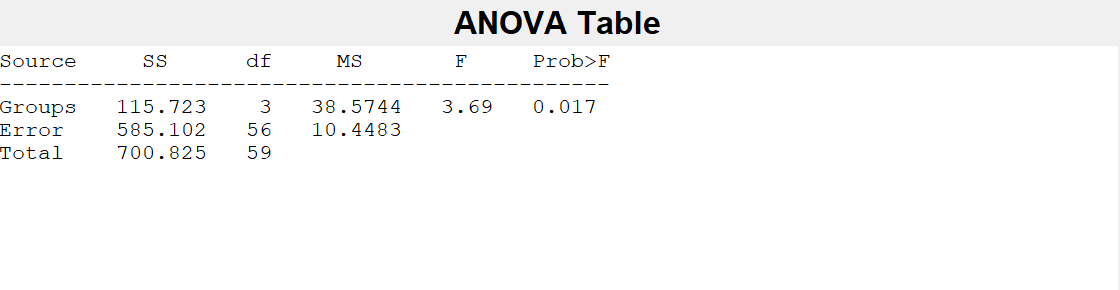

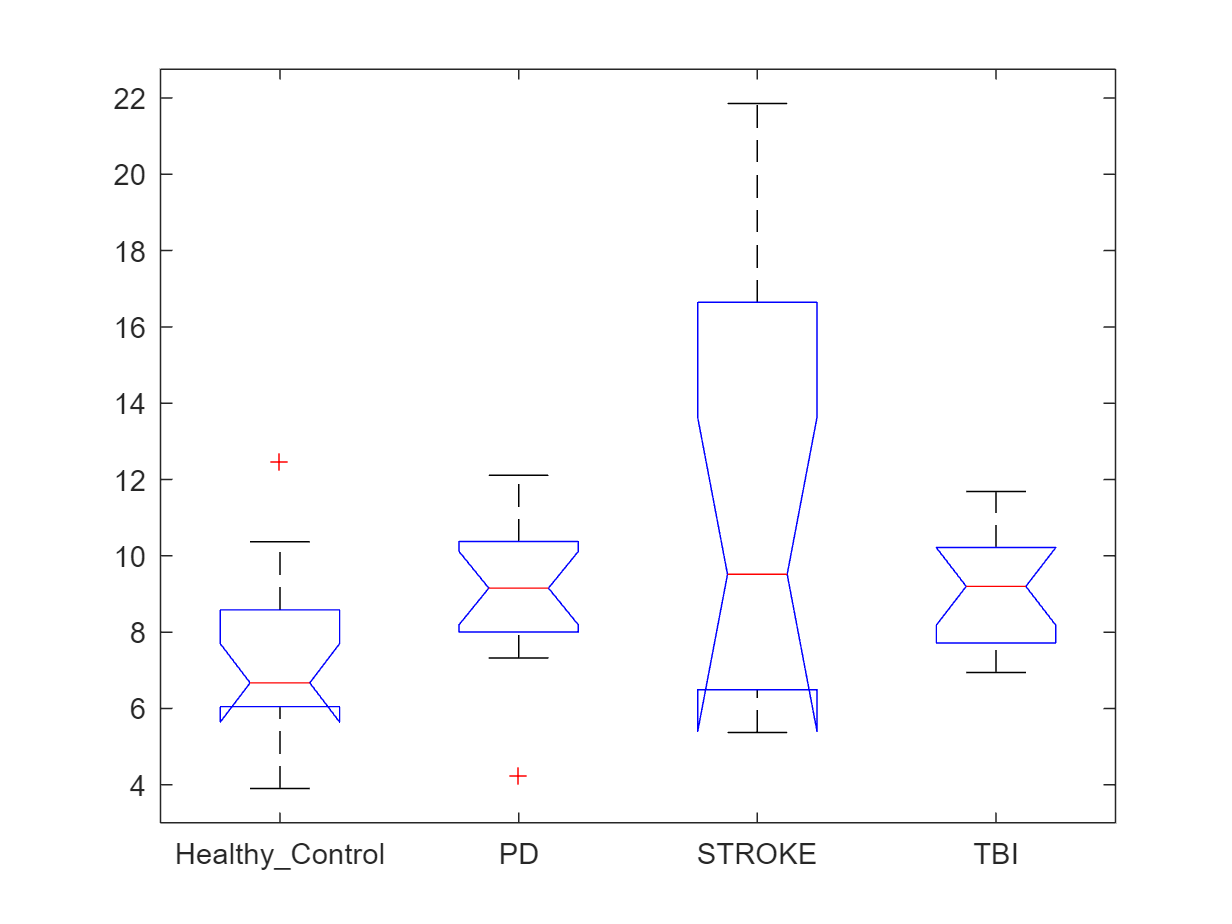

% Crea il vettore dei gruppi (15 per ciascuno)
%analisi statistica
n = 15;
gruppi = [repmat({'Healthy_Control'}, n, 1); ...
          repmat({'PD'}, n, 1); ...
          repmat({'STROKE'}, n, 1); ...
          repmat({'TBI'}, n, 1)];
gruppi = categorical(gruppi);

% Esempio: PCI = dati a caso (solo per test)
PCI = TABreduced.PCI_individuale;  

% ANOVA a una via
[p, tbl, stats] = anova1(PCI, gruppi);

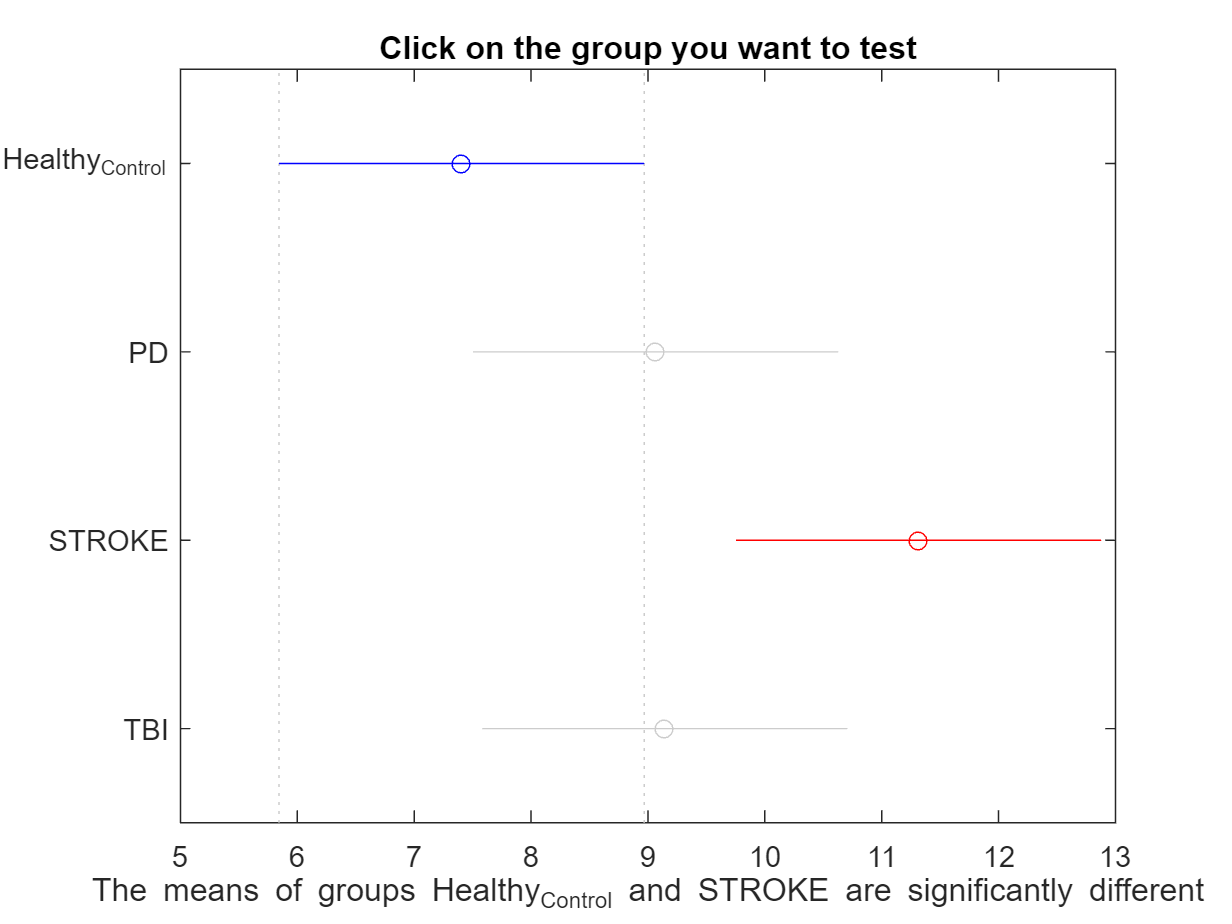

% Test post-hoc Tukey HSD
figure;
[c,~,~,gnames] = multcompare(stats);

%p-value per conferare differenze viste nel multcompare

tbl = array2table(c, 'VariableNames', ...
    ["GroupA", "GroupB", "LowerLimit", "A_B", "UpperLimit", "P_value"]);

tbl.GroupA = gnames(tbl.GroupA);
tbl.GroupB = gnames(tbl.GroupB)

tbl = 6×6 table
          GroupA             GroupB      LowerLimit       A_B       UpperLimit     P_value 
    ___________________    __________    __________    _________    __________    _________

    {'Healthy_Control'}    {'PD'    }      -4.7855       -1.6602       1.4651        0.5006
    {'Healthy_Control'}    {'STROKE'}      -7.0359       -3.9106     -0.78534     0.0085602
    {'Healthy_Control'}    {'TBI'   }      -4.8651       -1.7398       1.3855       0.45975
    {'PD'             }    {'STROKE'}      -5.3757       -2.2504      0.87489       0.23698
    {'PD'             }    {'TBI'   }      -3.2049     -0.079604       3.0457       0.99989
    {'STROKE'         }    {'TBI'   }     -0.95449        2.1708       5.2961       0.26617


**GAIT ASIMMETRY (GA)**

GA_individuale = zeros(height(TABreduced),1); % create new column

for ii = 1:height(TABreduced)
    swing_times = TABreduced.INDIP(ii).ContinuousWalkingPeriod.Swing_Duration;
    swing_side  = TABreduced.INDIP(ii).ContinuousWalkingPeriod.InitialContact_LeftRight;

    % Ensure these are columns
    swing_times = swing_times(:);
    swing_side = swing_side(:);

    right_idx_swing = [];
    left_idx_swing = [];

    % Separate right and left swings
    for c = 1:length(swing_side)
        if swing_side(c) == "Right"
            right_idx_swing = [right_idx_swing c];
        else
            left_idx_swing = [left_idx_swing c];
        end
    end

    % Assumptions: C = right, D = left
    GA = []; % Initialize GA for this individual

 if length(right_idx_swing) && ~isempty(left_idx_swing)
        for i = 1:(length(right_idx_swing)-1)
            C1 = swing_times(right_idx_swing(i));    
            C2 = swing_times(right_idx_swing(i+1));

    mid_L_idx_swing = find(swing_times(left_idx_swing) > C1 & swing_times(left_idx_swing) < C2);
        if ~isempty(mid_L_idx_swing) && all(left_idx_swing(mid_L_idx_swing) <= length(swing_times))
    D = swing_times(left_idx_swing(mid_L_idx_swing(1))); 
        end
            % Calculate GA for this pair (use log to calculate asymmetry)
            GA = 100 * log(mean(C1) / mean(D));

        end
    end
end

Index exceeds the number of array elements. Index must not exceed 20.


GA_individuale(ii) = GA; 
TABreduced.GA_individuale = GA_individuale;
    

**HEALTHY**

%% calcolo Healthy solo per TABreduced, prendendo i dati da 1 a 15 (tutti gli Healthy per il cammino rettilineo nella tabella ridotta)

for ii = 1:15  
    lb_acc_Healthy10 = TABreduced.LBACK(ii).acc; lb_acc_Healthy10 = fillmissing(lb_acc_Healthy10,'spline'); lb_acc_Healthy10 = bwfilt(lb_acc_Healthy10,2,128,10,'low');
    lb_gyr_Healthy10 = TABreduced.LBACK(ii).gyro; lb_gyr_Healthy10 = fillmissing(lb_gyr_Healthy10,'spline'); lb_gyr_Healthy10 = bwfilt(lb_gyr_Healthy10,2,128,6,'low');
    % 
    % st_acc = TAB10.STERN(ii).acc; st_acc = fillmissing(st_acc,'spline'); st_acc = bwfilt(st_acc,2,128,10,'low');
    % st_gyr = TAB10.STERN(ii).gyro; st_gyr = fillmissing(st_gyr,'spline'); st_gyr = bwfilt(st_gyr,2,128,6,'low');
    % 
    % fh_acc = TAB10.FHEAD(ii).acc; fh_acc = fillmissing(fh_acc,'spline'); fh_acc = bwfilt(fh_acc,2,128,10,'low');
    % fh_gyr = TAB10.FHEAD(ii).gyro; fh_gyr = fillmissing(fh_gyr,'spline'); fh_gyr = bwfilt(fh_gyr,2,128,6,'low');
    % 

    contacts = TABreduced.CONTANCTS{ii};
    side = TABreduced.SIDE{ii};

    [r,c] = (find(isnan(contacts))); r = unique(r); contacts(r,:) = []; %TAB.CONTANCTS{ii} = contacts;
    side(:,r) = []; %TAB.SIDE{ii} = side;
       

    for co = 1:length(contacts)
% if

    end
end

DST (Double support Time)

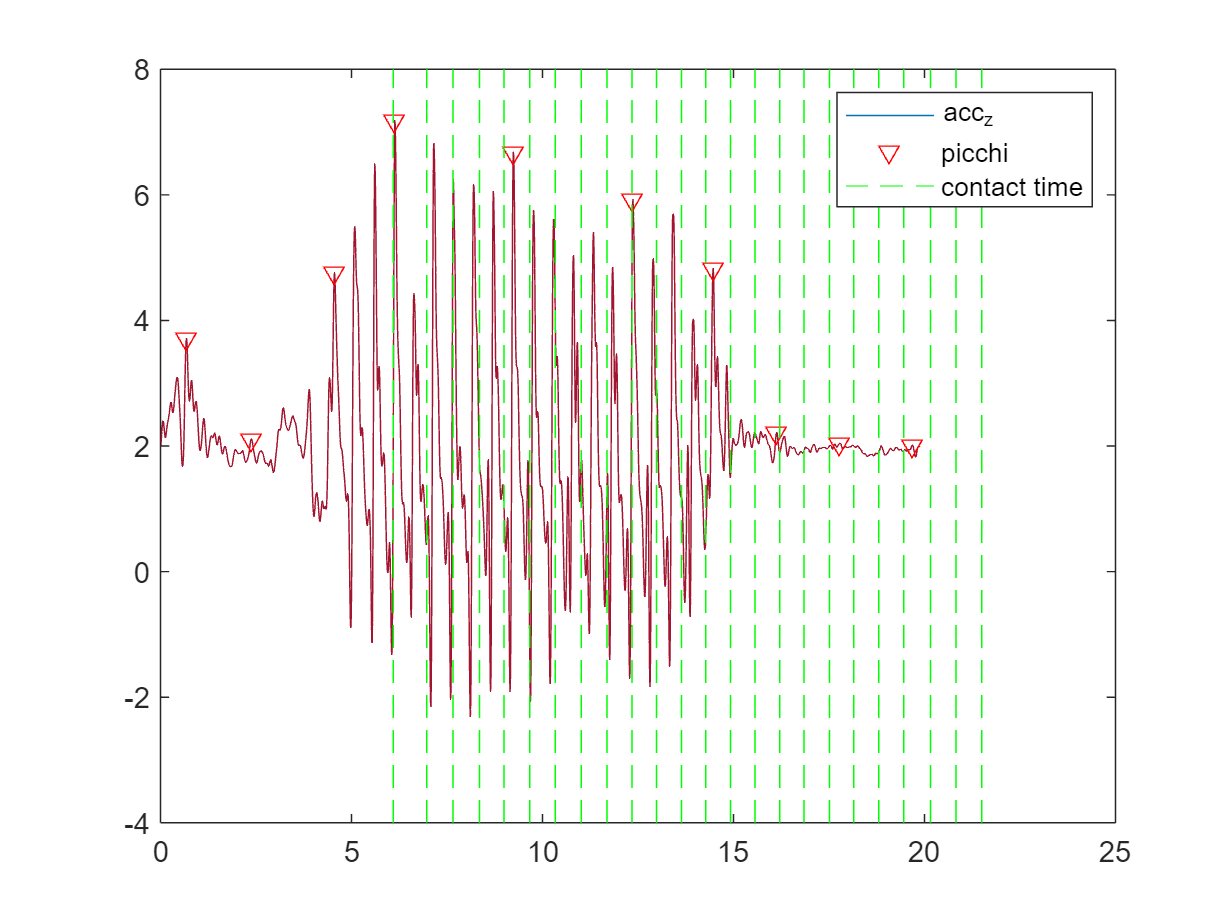

% Definisci un threshold per rilevare i picchi nei segnali di accelerazione
threshold = 0.5; % Modifica questo valore in base alla tua applicazione

% Trova i picchi nel segnale di accelerazione
acc_z = lb_acc_Healthy10(:,3); % Prendi solo la componente Z
[peaks, locs] = findpeaks(abs((acc_z)), 'MinPeakHeight', threshold, 'MinPeakDistance', 200); 

% Aggiungi un ciclo per associare i picchi con i contatti
heel_strikes = {}; % Inizializza una lista per i momenti di heel strike

% Associa i picchi ai momenti di contatto
for i = 1:length(ic_times)
    contact_time = ic_times(i); % Tempo del contatto
    side = ic_side(i);          % Sinistro o destro

    % Trova i picchi che avvengono vicino al tempo del contatto (0.8s)
    %dal grafico abbiamo visto la distanza tra una linea tratteggiata, che rappresenta il contact time, e
    %l'altra
 idx = find(locs/128 >= contact_time - 1 & locs/128 <= contact_time + 1);
t = (1:length(acc_z)) / 128; % asse dei tempi
plot(t, acc_z); hold on;
plot(locs/128, acc_z(locs), 'rv'); % picchi
xline(contact_time, 'g--'); % tempo del contatto
legend('acc_z','picchi','contact time');
    if ~isempty(idx)
        for j = 1:length(idx)
             
            heel_strikes{end+1,1} = contact_time;
            heel_strikes{end,  2} = side; % stringa 'Right' o 'Left'
            heel_strikes{end,  3} = locs(idx(j))/128; % tempo del picco
            heel_strikes{end,  4} = peaks(idx(j));
        end
    end
end

%nel workspace, in heel_strikes troviamo: prima colonna è il contact time
%(quando il piede tocca terra), la seconda (il piede), la terza (istante in
%cui si rileva un picco, che corrisponde a quando uno dei due piedi tocca
%terra), la quarta rappresenta il valore del picco dell'accelerazione del
%piede che tocca terra, vedi foto gruppo


%NON FUNZIONA
rs = heel_strikes(strcmp(heel_strikes(:,2),"Right"),1)


rs =

  0×1 empty cell array



ls = heel_strikes(strcmp(heel_strikes(:,2),"Left"),1)


ls =

  0×1 empty cell array



% STEP 2: CALCOLO DST PER OGNI CICLO
numCycles = min(length(rs), length(ls));
DST = zeros(numCycles-1,1);
for k = 2:numCycles

    % sovrapposizione: da max dei due contatti precedenti a min dei due successivi
    DST(k-1) = min(rs(k), ls(k)) - max(rs(k-1), ls(k-1));
end

% STEP 3: AGGIUNTA ALLA TABELLA
TABreduced.DST{ii}     = DST;                       % vettore DST per trial
TABreduced.MeanDST(ii) = mean(DST,'omitnan');      % media DST
TABreduced.CVDST(ii)   = 100 * std(DST,'omitnan') / TABreduced.MeanDST(ii);  % coeff. di variazione



## **PD**

%% calcolo PD solo per TAB10

for ii = 16:30
    lb_acc_PD10 = TAB10.LBACK(ii).acc; lb_acc_PD10 = fillmissing(lb_acc_PD10,'spline'); lb_acc_PD10 = bwfilt(lb_acc_PD10,2,128,10,'low');
    lb_gyr_PD10 = TAB10.LBACK(ii).gyro; lb_gyr_PD10 = fillmissing(lb_gyr_PD10,'spline'); lb_gyr_PD10 = bwfilt(lb_gyr_PD10,2,128,6,'low');

    % st_acc = TAB10.STERN(ii).acc; st_acc = fillmissing(st_acc,'spline'); st_acc = bwfilt(st_acc,2,128,10,'low');
    % st_gyr = TAB10.STERN(ii).gyro; st_gyr = fillmissing(st_gyr,'spline'); st_gyr = bwfilt(st_gyr,2,128,6,'low');
    % 
    % fh_acc = TAB10.FHEAD(ii).acc; fh_acc = fillmissing(fh_acc,'spline'); fh_acc = bwfilt(fh_acc,2,128,10,'low');
    % fh_gyr = TAB10.FHEAD(ii).gyro; fh_gyr = fillmissing(fh_gyr,'spline'); fh_gyr = bwfilt(fh_gyr,2,128,6,'low');


    contacts = TAB10.CONTANCTS{ii};
    side = TAB10.SIDE{ii};

    [r,c] = (find(isnan(contacts))); r = unique(r); contacts(r,:) = []; %TAB.CONTANCTS{ii} = contacts;
    side(:,r) = []; %TAB.SIDE{ii} = side;


    for co = 1:length(contacts)

%if
    end 
end

## ** ST**

for ii = 31:45
    lb_acc_ST10 = TAB10.LBACK(ii).acc; lb_acc_ST10 = fillmissing(lb_acc_ST10,'spline'); lb_acc_ST10 = bwfilt(lb_acc_ST10,2,128,10,'low');
    lb_gyr_ST10 = TAB10.LBACK(ii).gyro; lb_gyr_ST10 = fillmissing(lb_gyr_ST10,'spline'); lb_gyr_ST10 = bwfilt(lb_gyr_ST10,2,128,6,'low');

    % st_acc = TAB10.STERN(ii).acc; st_acc = fillmissing(st_acc,'spline'); st_acc = bwfilt(st_acc,2,128,10,'low');
    % st_gyr = TAB10.STERN(ii).gyro; st_gyr = fillmissing(st_gyr,'spline'); st_gyr = bwfilt(st_gyr,2,128,6,'low');
    % 
    % fh_acc = TAB10.FHEAD(ii).acc; fh_acc = fillmissing(fh_acc,'spline'); fh_acc = bwfilt(fh_acc,2,128,10,'low');
    % fh_gyr = TAB10.FHEAD(ii).gyro; fh_gyr = fillmissing(fh_gyr,'spline'); fh_gyr = bwfilt(fh_gyr,2,128,6,'low');


    contacts = TAB10.CONTANCTS{ii};
    side = TAB10.SIDE{ii};

    [r,c] = (find(isnan(contacts))); r = unique(r); contacts(r,:) = []; %TAB.CONTANCTS{ii} = contacts;
    side(:,r) = []; %TAB.SIDE{ii} = side;


    for co = 1:length(contacts)

%if
       
        end
end

% TBI
    %% For TBI (Traumatic Brain Injury)
    for ii = 46:60   
    lb_acc_TBI10 = TAB10.LBACK(ii).acc; lb_acc_TBI10 = fillmissing(lb_acc_TBI10,'spline'); lb_acc_TBI10 = bwfilt(lb_acc_TBI10,2,128,10,'low');
    lb_gyr_TBI10 = TAB10.LBACK(ii).gyro; lb_gyr_TBI10 = fillmissing(lb_gyr_TBI10,'spline'); lb_gyr_TBI10 = bwfilt(lb_gyr_TBI10,2,128,6,'low');

    % st_acc = TAB10.STERN(ii).acc; st_acc = fillmissing(st_acc,'spline'); st_acc = bwfilt(st_acc,2,128,10,'low');
    % st_gyr = TAB10.STERN(ii).gyro; st_gyr = fillmissing(st_gyr,'spline'); st_gyr = bwfilt(st_gyr,2,128,6,'low');
    % 
    % fh_acc = TAB10.FHEAD(ii).acc; fh_acc = fillmissing(fh_acc,'spline'); fh_acc = bwfilt(fh_acc,2,128,10,'low');
    % fh_gyr = TAB10.FHEAD(ii).gyro; fh_gyr = fillmissing(fh_gyr,'spline'); fh_gyr = bwfilt(fh_gyr,2,128,6,'low');


    contacts = TAB10.CONTANCTS{ii};
    side = TAB10.SIDE{ii};

    [r,c] = (find(isnan(contacts))); r = unique(r); contacts(r,:) = []; %TAB.CONTANCTS{ii} = contacts;
    side(:,r) = []; %TAB.SIDE{ii} = side;


    for co = 1:length(contacts)

%if
    end
    end